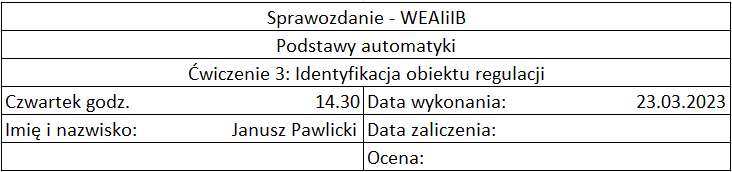

## 1. Wstęp

Celem ćwiczenia jest identyfikacja parametrów modelu rzeczywistego obiektu regulacji. Obiekt rzeczywisty jest obiektem nieskończenie wymiarowym, ale dla celów sterowania może być opisany poniższymi modelami transmitancyjnymi:

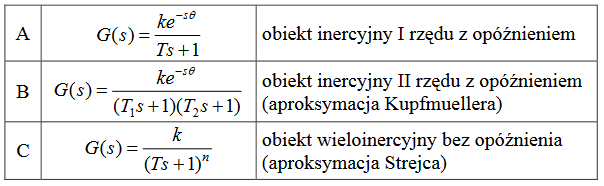

Parametry modelu:

             

## 2. Przebieg laboratorium

Załadownie tablicy danych

load("pomiary_3out.mat")
rozmiar = size(pomiary_3out);

### 2.1 Czujniki

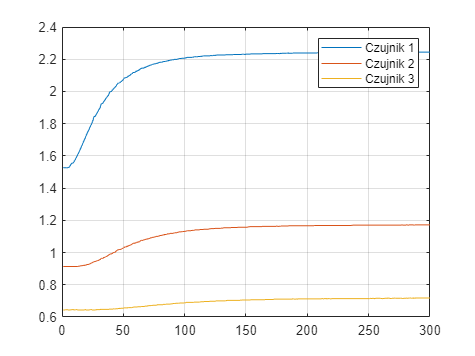

czas = 1:1:300;
plot(czas, pomiary_3out);
legend('Czujnik 1','Czujnik 2','Czujnik 3');
grid on;

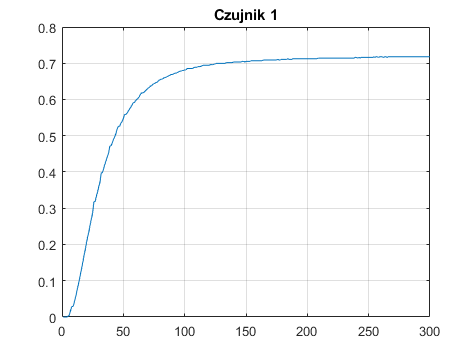

y1=pomiary_3out(:,1) - pomiary_3out(1,1);
y2=pomiary_3out(:,2) - pomiary_3out(1,2);
y3=pomiary_3out(:,3) - pomiary_3out(1,3);
figure();
plot(czas, y1);
title('Czujnik 1')
grid on;

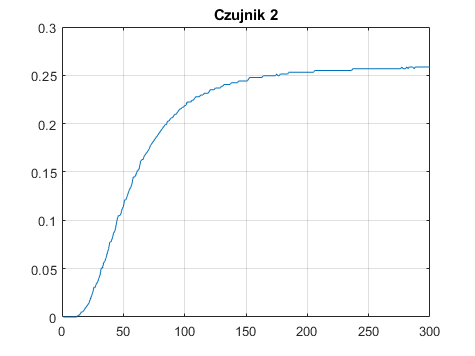

figure();
plot(czas, y2);
title('Czujnik 2')
grid on;

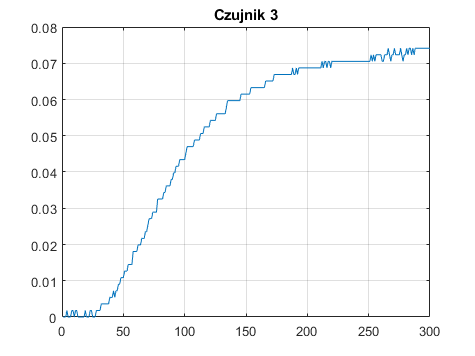

figure()
plot(czas, y3);
title('Czujnik 3')
grid on;

### 2.2 Czujnik 1

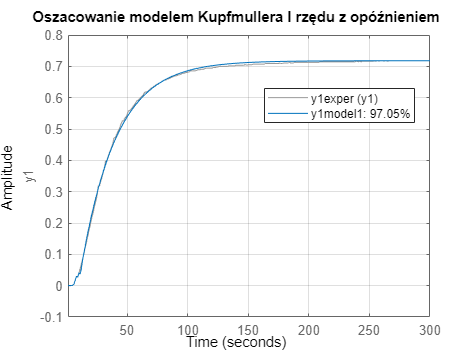

k1 = (y1(300,1)-y1(1,1))/1.0;
tau = 7.5;
[ld, md] = pade(tau, 10);
T = 29;
T1 = 4;
T2 = 28;
T1_2 = 16;
T2_2 = 20;
[l, m] = series(ld, md, [k1], [T 1]);
[l2, m2] = series(ld, md, [k1], [T1*T2, T1+T2, 1]);
l3 = [k1];
m3 = [T1_2*T2_2, T1_2+T2_2, 1];
y1m1 = step(l, m, czas);
y1m2 = step(l2, m2, czas);
y1m3 = step(l3, m3, czas);
u1 = ones(size(y1));
y1exper = iddata(y1, u1, 1);
y1model1 = tf(l, m);
y1model2 = tf(l2, m2);
y1model3 = tf(l3, m3);
compare(y1exper, y1model1, 300);
title('Oszacowanie modelem Kupfmullera I rzędu z opóźnieniem')
legend('Location', 'best')
grid on

MSE1_1 = sum((y1 - y1m1).^2)

MSE1_1 = 0.0432

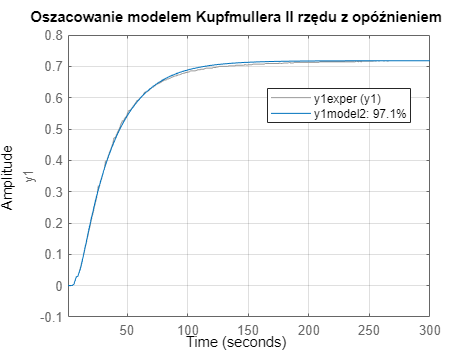

compare(y1exper, y1model2, 300);
title('Oszacowanie modelem Kupfmullera II rzędu z opóźnieniem')
legend('Location', 'best')
grid on

MSE1_2 = sum((y1 - y1m2).^2)

MSE1_2 = 0.0234

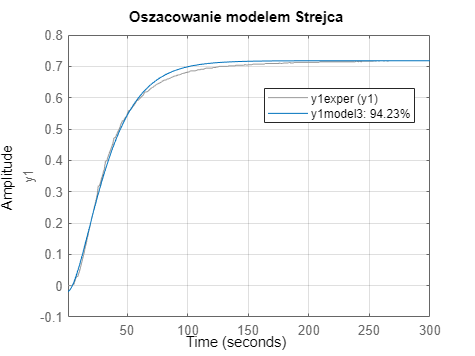

compare(y1exper, y1model3, 300);
title('Oszacowanie modelem Strejca')
legend('Location', 'best')
grid on

MSE1_3 = sum((y1 - y1m3).^2)

MSE1_3 = 0.0408

Najlepsze dopasowanie otrzymujemy z modelu Kupfmullera II rzędu.

### 2.3 Czujnik 2

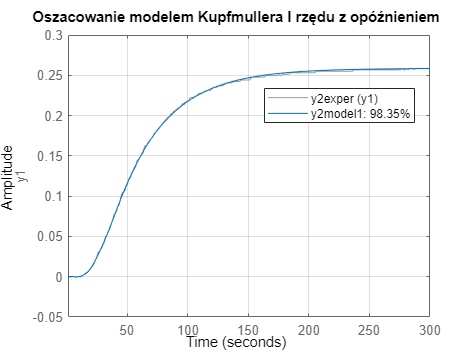

k2=(y2(300,1)-y2(1,1))/1.0;
tau = 50;
[ld, md] = pade(tau, 10);
T = 40;
T1 = 28;
T2 = 35;
T1_2 = 26;
T2_2 = 30;
[l, m] = series([k2], [T 1], ld, md);
[l2, m2] = series(ld, md, [k2], [T1*T2, T1+T2, 1]);
l3 = [k2];
m3 = [T1_2*T2_2, T1_2+T2_2, 1];
y2m1 = step(l, m, czas);
y2m2 = step(l2, m2, czas);
y2m3 = step(l3, m3, czas);
u2 = ones(size(y2));
y2exper = iddata(y2, u2, 1);
y2model1 = tf(l, m);
y2model2 = tf(l2, m2);
y2model3 = tf(l3, m3);
compare(y2exper, y2model1, 300);
title('Oszacowanie modelem Kupfmullera I rzędu z opóźnieniem')
legend('Location', 'best')
grid on

MSE2_1 = sum((y2 - y2m1).^2)

MSE2_1 = 0.4094

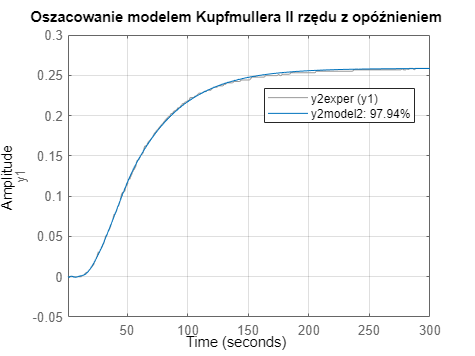

compare(y2exper, y2model2, 300);
title('Oszacowanie modelem Kupfmullera II rzędu z opóźnieniem')
legend('Location', 'best')
grid on

MSE2_2 = sum((y2 - y2m2).^2)

MSE2_2 = 1.1477

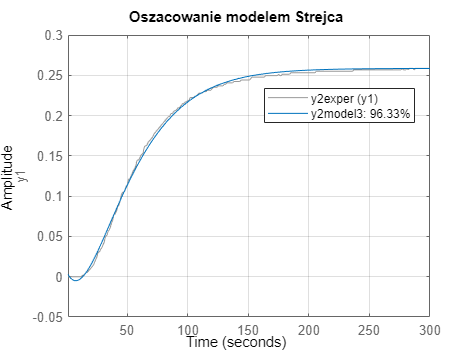

compare(y2exper, y2model3, 300);
title('Oszacowanie modelem Strejca')
legend('Location', 'best')
grid on

MSE2_3 = sum((y2 - y2m3).^2)

MSE2_3 = 0.0457

Najlepsze dopasowanie otrzymujemy z modelu Kupfmullera I rzędu. Wynik na poziomie 98%.

### 2.4 Czujnik 3

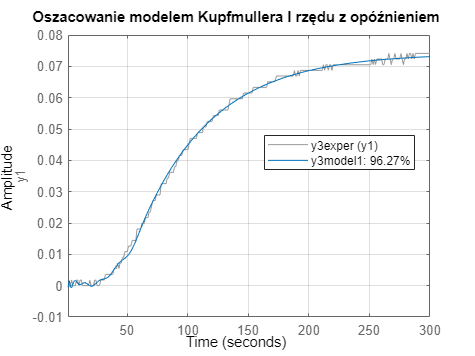

k3=(y3(300,1)-y3(1,1))/1.0;
tau = 50;
[ld, md] = pade(tau, 10);
T = 60;
T1 = 38;
T2 = 40;
T1_2 = 41;
T2_2 = 43;
[l, m] = series([k3], [T 1], ld, md);
[l2, m2] = series([k3], [T1*T2, T1+T2, 1], ld, md);
l3 = [k3];
m3 = [T1_2*T2_2, T1_2+T2_2, 1];
y3m1 = step(l, m, czas);
y3m2 = step(l2, m2, czas);
y3m3 = step(l3, m3, czas);
u3 = ones(size(y3));
y3exper = iddata(y3, u3, 1);
y3model1 = tf(l, m);
y3model2 = tf(l2, m2);
y3model3 = tf(l3, m3);
compare(y3exper, y3model1, 300);
title('Oszacowanie modelem Kupfmullera I rzędu z opóźnieniem')
legend('Location', 'best')
grid on

MSE1 = sum((y3 - y3m1).^2)

MSE1 = 0.0026

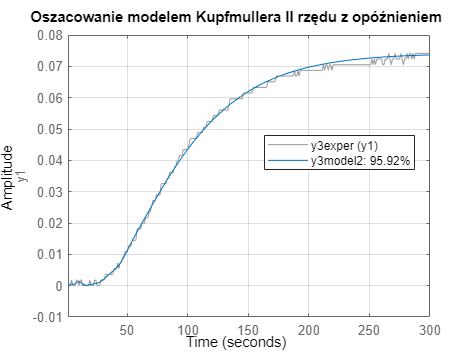

compare(y3exper, y3model2, 300);
title('Oszacowanie modelem Kupfmullera II rzędu z opóźnieniem')
legend('Location', 'best')
grid on

MSE2 = sum((y3 - y3m2).^2)

MSE2 = 0.0256

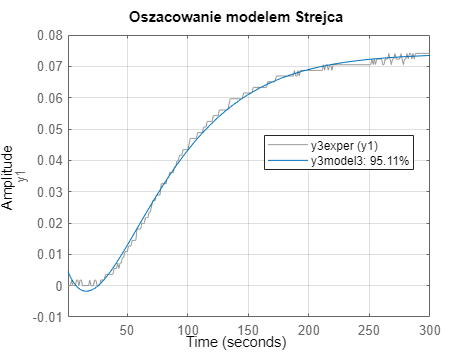

compare(y3exper, y3model3, 300);
title('Oszacowanie modelem Strejca')
legend('Location', 'best')
grid on

MSE3 = sum((y3 - y3m3).^2)

MSE3 = 0.0114

Najlepszy wynik dla modelu Kupfmullera I rzędu, lecz pozostałem modele dały równie dobre wyniki.

## 3. Wnioski

Ćwiczenie po opracowaniu kodu dla pierwszego czujnika było już proste, lecz na początku pojawiały się dla mnie trudności. Dokładne zapoznanie z różnymi modelami identyfikacjami. Najlepiej dla wszytkich sprawdzał się model Kupfmullera II rzędu. Natomiast w zależności od przykładu inne modele dawały nieco lepsze rezultaty. Ogólnie słabo wypadł model Strejca, natomiast w zależności od parametrów jest on w stanie dobrze się dopaswywać.